Task1

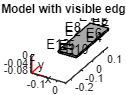

%dimms
X=0.1;
Y=0.3;
Z=0.01;
E=2.1*10^11; %young's modulus
rho=7800; %density
nu=0.3; %poisson's ratio
%create object surface
modelM = createpde('structural','modal-solid');
%generate 3D structure
gm = multicuboid(X,Y,Z);
modelM.Geometry = gm;
%displaying the model
figure(1)
pdegplot(modelM,'EdgeLabels','on');
axis equal
title 'Model with visible edges'

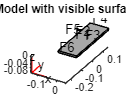

figure(2)
pdegplot(modelM,'FaceLabels','on');
axis equal
title 'Model with visible surfaces'

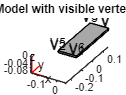

figure(3)
pdegplot(modelM,'VertexLabels','on');
axis equal
title 'Model with visible vertexes'

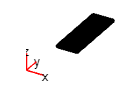

%generate FEM of the object
hmax = 8e-3;
msh = generateMesh(modelM,'Hmax',hmax);
%display FEM
figure(4)
pdeplot3D(modelM);
axis equal

%give FEM properties
structuralProperties(modelM,'YoungsModulus',E, ...
 'PoissonsRatio',nu, ...
'MassDensity',rho);
%define full restraint on surface 6
structuralBC(modelM,'Face',6,'Constraint','fixed');
%simulate FEM model
resModal = solve(modelM,'FrequencyRange',[0,1000]*2*pi);
%display the eigenfrequencies stored in the resModal
modeID = 1:numel(resModal.NaturalFrequencies);
tmodalResults = table(modeID.',resModal.NaturalFrequencies/(2*pi));
tmodalResults.Properties.VariableNames = {'Mode','Frequency'};
disp(tmodalResults)

    Mode    Frequency
    ____    _________

     1       94.804  
     2       565.48  
     3       589.72  
     4       865.07  



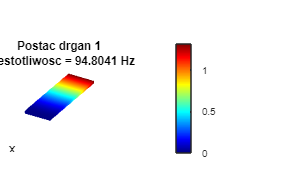

Stopped by user


%display the shape corresponding to a given frequency
ModeNumber = 1;
FrameRate = 30;
AnimateModeShape(resModal,ModeNumber,FrameRate)

Task2.1

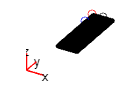

A=[-0.05 0.15 0.01];
B=[-0.05 0.0866 0.01];
C=[0 0.15 0.01];
%generate model
modelFR = createpde('structural','frequency-solid');
%Assign geometry, mesh, material properties, and boundary conditions
modelFR.Geometry = modelM.Geometry;
modelFR.Mesh = modelM.Mesh;
structuralProperties(modelFR,'YoungsModulus',E,'PoissonsRatio',...
nu,'MassDensity', rho);
structuralBC(modelFR,'Face',6,'Constraint','fixed');
%assume damping
structuralDamping(modelFR,'Zeta',0.001);
%apply force
Fz = 1;
Fx=0;
Fy=0;
VertexNo = 8;
structuralBoundaryLoad(modelFR,'Vertex',VertexNo,'Force',[Fx,Fy,Fz]);
%, run the simulation assuming a range of frequencies
flist = linspace(0,999,1000)*2*pi;
resFreq = solve(modelFR,flist,'ModalResults',resModal);
%obtain frequency response
[FRFAd,FreqAd] = DisplayFRF(resFreq,A,'displacement');
[FRFBd,FreqBd] = DisplayFRF(resFreq,B,'displacement');
[FRFCd,FreqCd] = DisplayFRF(resFreq,C,'displacement');

[FRFAv,FreqAv] = DisplayFRF(resFreq,A,'velocity');
[FRFBv,FreqBv] = DisplayFRF(resFreq,B,'velocity');
[FRFCv,FreqCv] = DisplayFRF(resFreq,C,'velocity');

[FRFAa,FreqAa] = DisplayFRF(resFreq,A,'acceleration');
[FRFBa,FreqBa] = DisplayFRF(resFreq,B,'acceleration');
[FRFCa,FreqCa] = DisplayFRF(resFreq,C,'acceleration');
%checking if the positions of the analysis points are correct
figure
pdeplot3D(modelM);
hold on
plot3(A(1),A(2),A(3),'ro')
plot3(B(1),B(2),B(3),'bo')
plot3(C(1),C(2),C(3),'ko')
hold off
axis equal

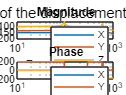

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFAd);  % Magnitude of FRF
FRF_phase = angle(FRFAd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqAd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqAd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point A')

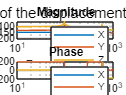

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFBd);  % Magnitude of FRF
FRF_phase = angle(FRFBd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqBd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqBd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point B')

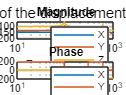

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFCd);  % Magnitude of FRF
FRF_phase = angle(FRFCd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqCd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqCd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point C')

Task 2.2

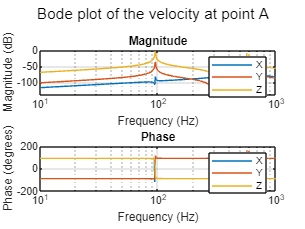

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFAv);  % Magnitude of FRF
FRF_phase = angle(FRFAv) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqAv, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqAv, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the velocity at point A')

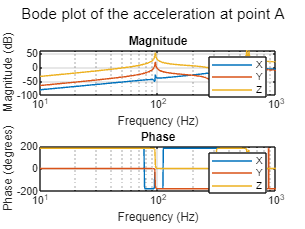

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFAa);  % Magnitude of FRF
FRF_phase = angle(FRFAa) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqAa, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqAa, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the acceleration at point A')

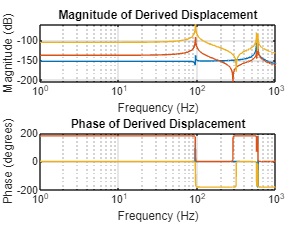

% Expand omega to match the dimensions of FRFAv
omega_matrix = repmat(omega.', [1, 3]);  % Transpose omega and replicate across columns

% Displacement from Velocity (Integration)
Xf = FRFAv ./ (1j * omega_matrix);  % Ensure omega_matrix is used here
Xf_magnitude = abs(Xf);
Xf_phase = angle(Xf) * (180/pi);

% Acceleration from Velocity (Differentiation)
Af = FRFAv .* (1j * omega_matrix);  % Ensure omega_matrix is used here
Af_magnitude = abs(Af);
Af_phase = angle(Af) * (180/pi);

% Plotting the derived displacement
figure;
subplot(2, 1, 1);
semilogx(FreqAv, 20*log10(Xf_magnitude));  % dB conversion for magnitude
title('Magnitude of Derived Displacement');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

subplot(2, 1, 2);
semilogx(FreqAv, Xf_phase);
title('Phase of Derived Displacement');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

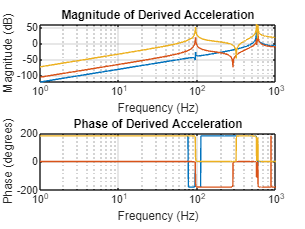


% Plotting the derived acceleration
figure;
subplot(2, 1, 1);
semilogx(FreqAv, 20*log10(Af_magnitude));  % dB conversion for magnitude
title('Magnitude of Derived Acceleration');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

subplot(2, 1, 2);
semilogx(FreqAv, Af_phase);
title('Phase of Derived Acceleration');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

Task 2.3

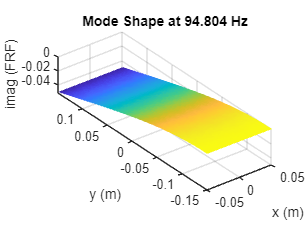

[~,ModeShape,Xv,Yv,Zv] = DisplayMode(resFreq,modelFR,0.01,3,94.804);
ModeZ = imag(ModeShape);
scale = max(Xv)./max(abs(ModeZ(:)));
figure
tri = delaunay(Xv,Yv);
trisurf(tri,Xv,Yv,ModeZ*scale);
axis equal
shading flat
xlabel('x (m)'); ylabel('y (m)'); zlabel('imag (FRF)');
title('Mode Shape at 94.804 Hz')

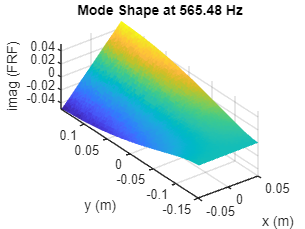

[~,ModeShape,Xv,Yv,Zv] = DisplayMode(resFreq,modelFR,0.01,3,565.48);
ModeZ = imag(ModeShape);
scale = max(Xv)./max(abs(ModeZ(:)));
figure
tri = delaunay(Xv,Yv);
trisurf(tri,Xv,Yv,ModeZ*scale);
axis equal
shading flat
xlabel('x (m)'); ylabel('y (m)'); zlabel('imag (FRF)');
title('Mode Shape at 565.48 Hz')

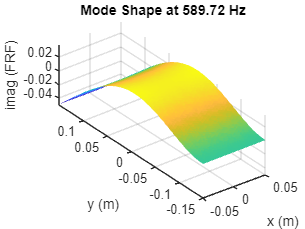

[~,ModeShape,Xv,Yv,Zv] = DisplayMode(resFreq,modelFR,0.01,3,589.72);
ModeZ = imag(ModeShape);
scale = max(Xv)./max(abs(ModeZ(:)));
figure
tri = delaunay(Xv,Yv);
trisurf(tri,Xv,Yv,ModeZ*scale);
axis equal
shading flat
xlabel('x (m)'); ylabel('y (m)'); zlabel('imag (FRF)');
title('Mode Shape at 589.72 Hz')

Task 2.4

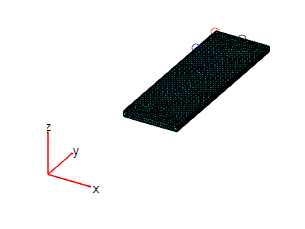

A=[-0.05 0.15 0.01];
B=[-0.05 0.0866 0.01];
C=[0 0.15 0.01];
%generate model
modelFR = createpde('structural','frequency-solid');
%Assign geometry, mesh, material properties, and boundary conditions
modelFR.Geometry = modelM.Geometry;
modelFR.Mesh = modelM.Mesh;
structuralProperties(modelFR,'YoungsModulus',E,'PoissonsRatio',...
nu,'MassDensity', rho);
structuralBC(modelFR,'Face',6,'Constraint','fixed');
%assume damping
structuralDamping(modelFR,'Zeta',0.003);
%apply force
Fz = 1;
Fx=0;
Fy=0;
VertexNo = 8;
structuralBoundaryLoad(modelFR,'Vertex',VertexNo,'Force',[Fx,Fy,Fz]);
%, run the simulation assuming a range of frequencies
flist = linspace(0,999,1000)*2*pi;
resFreq = solve(modelFR,flist,'ModalResults',resModal);
%obtain frequency response
[FRFAd,FreqAd] = DisplayFRF(resFreq,A,'displacement');
[FRFBd,FreqBd] = DisplayFRF(resFreq,B,'displacement');
[FRFCd,FreqCd] = DisplayFRF(resFreq,C,'displacement');

[FRFAv,FreqAv] = DisplayFRF(resFreq,A,'velocity');
[FRFBv,FreqBv] = DisplayFRF(resFreq,B,'velocity');
[FRFCv,FreqCv] = DisplayFRF(resFreq,C,'velocity');

[FRFAa,FreqAa] = DisplayFRF(resFreq,A,'acceleration');
[FRFBa,FreqBa] = DisplayFRF(resFreq,B,'acceleration');
[FRFCa,FreqCa] = DisplayFRF(resFreq,C,'acceleration');
%checking if the positions of the analysis points are correct
figure
pdeplot3D(modelM);
hold on
plot3(A(1),A(2),A(3),'ro')
plot3(B(1),B(2),B(3),'bo')
plot3(C(1),C(2),C(3),'ko')
hold off
axis equal

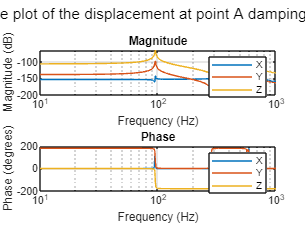

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFAd);  % Magnitude of FRF
FRF_phase = angle(FRFAd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqAd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqAd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point A damping 3%')

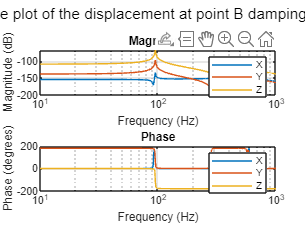

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFBd);  % Magnitude of FRF
FRF_phase = angle(FRFBd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqBd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqBd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point B damping 3%')

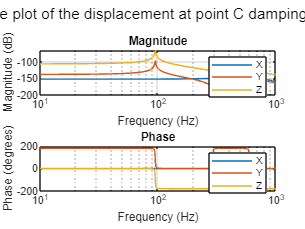

% Extract complex components (assuming FRF is already complex)
FRF_mag = abs(FRFCd);  % Magnitude of FRF
FRF_phase = angle(FRFCd) * (180/pi);  % Phase of FRF in degrees

% Plot Bode plot (magnitude and phase)
figure();
% Magnitude plot (dB)
subplot(2, 1, 1);
semilogx(FreqCd, 20*log10(FRF_mag));  % Convert magnitude to dB
title(['Magnitude']);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
% Phase plot (degrees)
subplot(2, 1, 2);
semilogx(FreqCd, FRF_phase);
title(['Phase']);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;
xlim([10^1 10^3])
legend('X','Y','Z')
sgtitle('Bode plot of the displacement at point C damping 3%')

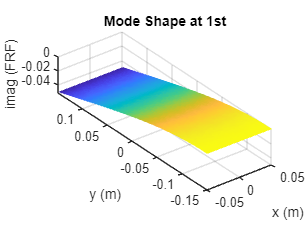

first_three_freq = resModal.NaturalFrequencies(1:3);
Zlayer = 0.01; % Top of the tile
Axis = 3; % Displacement in the Z axis


    fc = first_three_freq(i); % Current frequency
    [~, ModeShape, Xv, Yv, Zv] = DisplayMode(resFreq, modelFR, Zlayer, Axis, fc); % Display mode shape
    fcs=[94.804 565.48 589.72];
    [FN,DR,MS] = modalfit(FRFmap,FreqAd,2000,4,'FreqRange',([0 1000]),'FitMethod','lsce','PhysFreq',fcs);
    % Use the imaginary part of the ModeShape
    ModeZ = imag(MS);
    scale = max(Xv) / max(abs(ModeZ(:,1))); % Scale factor for visualization

    % Plotting the mode shape
    figure;
    tri = delaunay(Xv, Yv); % Create a Delaunay triangulation for plotting
    trisurf(tri, Xv, Yv, ModeZ(:,1) * scale); % Plot the triangulated surface
    axis equal;
    shading flat;
    xlabel('x (m)');
    ylabel('y (m)');
    zlabel('imag (FRF)');
    title(sprintf('Mode Shape at 1st', fc/(2*pi))); % Title with frequency in Hz

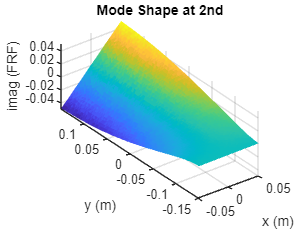


    fc = first_three_freq(i); % Current frequency
    [~, ModeShape, Xv, Yv, Zv] = DisplayMode(resFreq, modelFR, Zlayer, Axis, fc); % Display mode shape
    fcs=[94.804 565.48 589.72];
    [FN,DR,MS] = modalfit(FRFmap,FreqAd,2000,4,'FreqRange',([0 1000]),'FitMethod','lsce','PhysFreq',fcs);
    % Use the imaginary part of the ModeShape
    ModeZ = imag(MS);
    scale = max(Xv) / max(abs(ModeZ(:,2))); % Scale factor for visualization

    % Plotting the mode shape
    figure;
    tri = delaunay(Xv, Yv); % Create a Delaunay triangulation for plotting
    trisurf(tri, Xv, Yv, ModeZ(:,2) * scale); % Plot the triangulated surface
    axis equal;
    shading flat;
    xlabel('x (m)');
    ylabel('y (m)');
    zlabel('imag (FRF)');
    title(sprintf('Mode Shape at 2nd', fc/(2*pi))); % Title with frequency in Hz

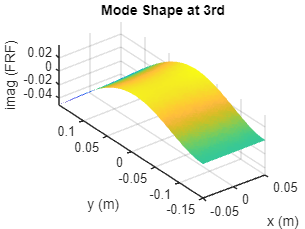


    fc = first_three_freq(i); % Current frequency
    [~, ModeShape, Xv, Yv, Zv] = DisplayMode(resFreq, modelFR, Zlayer, Axis, fc); % Display mode shape
    fcs=[94.804 565.48 589.72];
    [FN,DR,MS] = modalfit(FRFmap,FreqAd,2000,4,'FreqRange',([0 1000]),'FitMethod','lsce','PhysFreq',fcs);
    % Use the imaginary part of the ModeShape
    ModeZ = imag(MS);
    scale = max(Xv) / max(abs(ModeZ(:,3))); % Scale factor for visualization

    % Plotting the mode shape
    figure;
    tri = delaunay(Xv, Yv); % Create a Delaunay triangulation for plotting
    trisurf(tri, Xv, Yv, ModeZ(:,3) * scale); % Plot the triangulated surface
    axis equal;
    shading flat;
    xlabel('x (m)');
    ylabel('y (m)');
    zlabel('imag (FRF)');
    title(sprintf('Mode Shape at 3rd', fc/(2*pi))); % Title with frequency in Hz

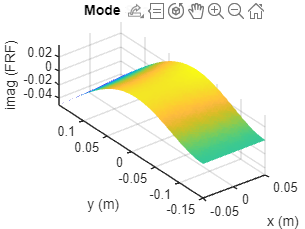

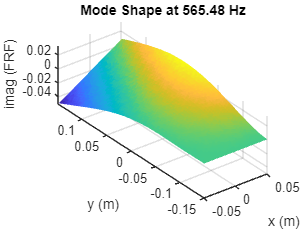

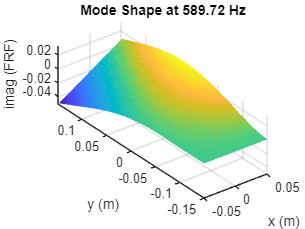

for i = 1:3 % For each of the first three eigenfrequencies
    fc = first_three_freq(i); % Current frequency
    [~, ModeShape, Xv, Yv, Zv] = DisplayMode(resFreq, modelFR, Zlayer, Axis, fc); % Display mode shape

    % Use the imaginary part of the ModeShape
    ModeZ = imag(ModeShape);
    scale = max(Xv) / max(abs(ModeZ(:))); % Scale factor for visualization

    % Plotting the mode shape
    figure;
    tri = delaunay(Xv, Yv); % Create a Delaunay triangulation for plotting
    trisurf(tri, Xv, Yv, ModeZ * scale); % Plot the triangulated surface
    axis equal;
    shading flat;
    xlabel('x (m)');
    ylabel('y (m)');
    zlabel('imag (FRF)');
    title(sprintf('Mode Shape at %.2f Hz', fc/(2*pi))); % Title with frequency in Hz
end